# SINUSOID GENERATION

function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    % INPUT
    % a: Amplitude
    % f: Frequency of sinusoid (in Hz)
    % phi: Phase (multiples of 2pi)
    % fs: sampling frequency (in Hz)
    % T_s: duration (in seconds)
    
    % OUTPUT:
    % time_vector: Time vector with sampling points
    % signal: Output signal

    % Calculate time_vector:
    % Vector from 0 to T_s with increments of 1/fs
    time_vector = 0:1/fs:T_s;

    % Generate sinusoidal signal:
    signal = a*sin(2*pi*f*time_vector+phi);
end

## a) CLEAN 1000Hz SIGNAL

% Signal parameters
a = 1

a = 1

f = 1000

f = 1000

phi = 0

phi = 0

fs = 44100

fs = 44100

T_s = 0.5

T_s = 0.5000


% Generating the signal
[timV, clean1000] = generate_sinusoid(a, f, phi, fs, T_s);

deviceID = 1;

## Recorded signal

% Use this if you have the file on your pc!!
% Loading recorded signal
[singing, sing_fs] = audioread("C:\DTU\signals_discrete\assignment1\doremifasol.wav");

% Making sure that both signals have the same length
singing = singing(1:length(clean1000));

## Recording new signal!!

nBits = 16;
nChannels = 1; % mono audio
recObj = audiorecorder(fs, nBits, nChannels, deviceID);

% Recording 0.5s audio
disp("Starting the recording...");

Starting the recording...


recordblocking(recObj, T_s);
disp("End of recording...");

End of recording...



% Verifying if the audio has been recorded
if isempty(getaudiodata(recObj))
    disp('Error: No audio recorded');
else
    % Obtener los datos de audio
    audioData = getaudiodata(recObj);

    % Guardar los datos de audio en un archivo WAV
    filename = 'doremifasol.wav';
    audiowrite(filename, audioData, fs);

    disp(['The audio file has been saved as ', filename]);
end

The audio file has been saved as doremifasol.wav



% Loading recorded signal
[singing, sing_fs] = audioread("doremifasol.wav");

% Making sure that both signals have the same length
singing = singing(1:length(clean1000));

Index exceeds the number of array elements. Index must not exceed 22050.

sound(audioData, fs)

## Plotting both signals

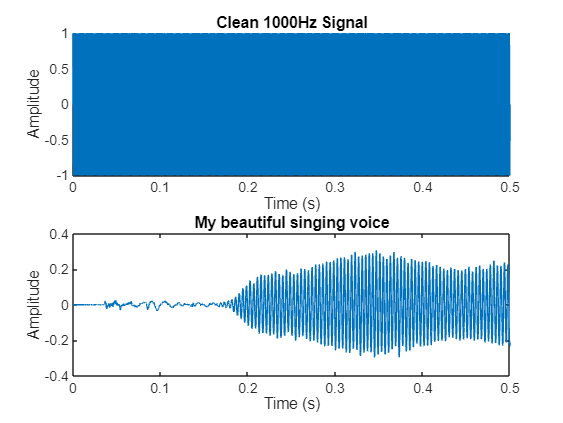

figure;

subplot(2,1,1)
plot(timV, clean1000);
title("Clean 1000Hz Signal");
xlabel("Time (s)");
ylabel("Amplitude");

subplot(2,1,2)
plot(timV, singing);
title("My beautiful singing voice");
xlabel("Time (s)");
ylabel("Amplitude");

## Zooming in...

zoom = 0:1/fs:0.005

zoom =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011


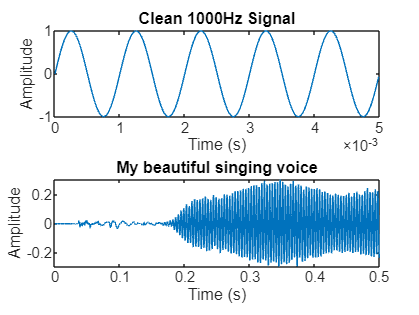


figure;

subplot(2,1,1)
plot(zoom, clean1000(1:length(zoom)));
title("Clean 1000Hz Signal");
xlabel("Time (s)");
ylabel("Amplitude");


subplot(2,1,2)
plot(timV, singing);
title("My beautiful singing voice");
xlabel("Time (s)");
ylabel("Amplitude");

## b) Magnitude spectrum

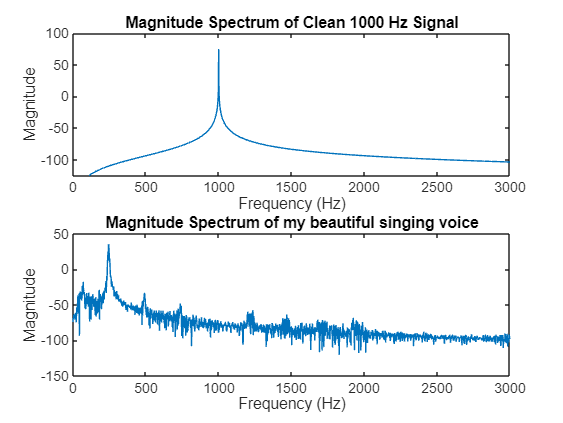

% Computing the Fourier Transform of both signals
N = length(clean1000);
clean_ft = fft(clean1000);

N1 = length(singing);
sing_ft = fft(singing);

% Computing the magnitud spectra
cleanMagnitude = abs(clean_ft.^2/N);
cleanMagnitude = 20*log10(cleanMagnitude);

singMagnitude = abs(sing_ft.^2/N1);
singMagnitude = 20*log10(singMagnitude);

% Frequency vector
freqV = linspace(-fs/2, fs/2, N);

% Plot the magnitude spectra
figure;
subplot(2,1,1);
plot(freqV, fftshift(cleanMagnitude));
title("Magnitude Spectrum of Clean 1000 Hz Signal")
xlabel("Frequency (Hz)");
ylabel("Magnitude");
xlim([0 3000]);
ylim([-125 100]);

subplot(2,1,2);
plot(freqV, fftshift(singMagnitude));
title("Magnitude Spectrum of my beautiful singing voice");
xlabel("Frequency (Hz)");
ylabel("Magnitude");
xlim([0 3000]);